# REGALS analysis of PheH titration data

**Data were originally published in:**

Meisburger SP, Taylor AB, Khan CA, Zhang S, Fitzpatrick PF, Ando N. *Domain movements upon activation of phenylalanine hydroxylase characterized by crystallography and chromatography-coupled small-angle X-ray scattering. *JACS 138(20): 6506?16 (2016). [http://dx.doi.org/10.1021/jacs.6b01563](http://dx.doi.org/10.1021/jacs.6b01563)

addpath('../matlab/'); % add REGALS code to path

## Load data

load data/PheH_titration.mat q I sigma phe name
fprintf(1,'loaded datasets:\n');

loaded datasets:


fprintf(1,'  %s\n',name{:});

  pheh_25um_tbuf_phe0_A1_153
  pheh_25um_tbuf_phe50_A1_171
  pheh_25um_tbuf_phe100_A1_169
  pheh_25um_tbuf_phe150_A1_173
  pheh_25um_tbuf_phe200_A1_158
  pheh_25um_tbuf__phe300_A1_160
  pheh_25um_tbuf_phe400_A1_162
  pheh_25um_tbuf_phe500_A1_164
  pheh_25um_tbuf_phe600_A1_166
  pheh_25um_tbuf_phe1000_C9_148
  pheh_25um_tbuf_phe3000_C9_146
  pheh_25um_tbuf_phe6000_C9_144
  pheh_25um_tbuf_phe10000_A1_151
  pheh_25um_tbuf_phe20000_19
  pheh_25um_tbuf_phe40000_17
  pheh_25um_tbuf_phe80000_15


## Set up REGALS calculation

Each component has a peak (concenetration) and profile regularizer.

x = log10(phe); % we'll seek smoothness on a logarithmic scale
x(1) = 1; % assign 10 micromolar for [phe] = 0 point

C1 = Component(...
    Concentration(x,'smooth',...
        'xmin',1 - 1E-3,...
        'xmax',3.5 + 1E-3,...
        'isZeroAtXmin',false,...
        'isZeroAtXmax',true,...
        'Nw',21),...
    Profile(q,'realspace','dmax',130,'Nw',101));

C2 = Component(...
    Concentration(x,'smooth',...
        'xmin',1 - 1E-3,...
        'xmax',5 + 1E-3,...
        'isZeroAtXmin',true,...
        'isZeroAtXmax',false,...
        'Nw',31),...
    Profile(q,'realspace','dmax',130,'Nw',101));

C3 = Component(...
    Concentration(x,'smooth',...
    'xmin',1 - 1E-3,...
    'xmax',5 + 1E-3,...
    'isZeroAtXmin',false,...
    'isZeroAtXmax',false,...
    'Nw',31),...
    Profile(q,'realspace','dmax',300,'Nw',101));

M = Mixture([C1,C2,C3]);
M.concentrationLambda = [1E1,1E1,1E1];
M.profileLambda = [1E12,1E12,1E12];

## Run REGALS

R = REGALS(I,sigma); % creat REGALS object

% set stopFun to return true when 50 iterations is exceeded
stopFun = @(iter,params) deal(iter >=  50,'maxIter');

updateFun = @(iter,NewMix,params,resid) ...
    fprintf(1,'%2d, x2 = %f, delta_profile = %s\n',...
    iter,params.x2,mat2str(params.delta_profile,3));

% run REGALS
[M1,params,resid] = R.run(M,stopFun,updateFun);

 1, x2 = 29.057538, delta_profile = [981 1.2e+03 537]
 2, x2 = 35.925201, delta_profile = [980 1.2e+03 531]
 3, x2 = 7.612028, delta_profile = [1.69 0.729 1.96]
 4, x2 = 7.349475, delta_profile = [1.06 0.177 0.745]
 5, x2 = 7.300829, delta_profile = [0.0375 0.0277 0.241]
 6, x2 = 7.258425, delta_profile = [0.0198 0.0331 0.0682]
 7, x2 = 7.212980, delta_profile = [0.022 0.0375 0.0877]
 8, x2 = 7.137376, delta_profile = [0.0275 0.0449 0.112]
 9, x2 = 6.999705, delta_profile = [0.0339 0.0546 0.145]
10, x2 = 6.742969, delta_profile = [0.0425 0.0675 0.187]
11, x2 = 6.275013, delta_profile = [0.0537 0.085 0.24]
12, x2 = 5.506465, delta_profile = [0.0678 0.109 0.303]
13, x2 = 4.506710, delta_profile = [0.0846 0.138 0.36]
14, x2 = 3.572843, delta_profile = [0.101 0.172 0.377]
15, x2 = 2.913388, delta_profile = [0.113 0.197 0.311]
16, x2 = 2.497186, delta_profile = [0.116 0.196 0.208]
17, x2 = 2.228608, delta_profile = [0.105 0.175 0.13]
18, x2 = 2.042685, delta_profile = [0.089 0.148 0.0872]
1

## Extract results to plot

% P(r) functions
r1 = M1.Components(1).Profile.w;
pr1 = [0;M1.uProfile{1};0];

r2 = M1.Components(2).Profile.w;
pr2 = [0;M1.uProfile{2};0];

r3 = M1.Components(3).Profile.w;
pr3 = [0;M1.uProfile{3};0];

% Particle components (extracted)
[I1,sigma1] = M1.extractProfile(I,sigma,1);
[I2,sigma2] = M1.extractProfile(I,sigma,2);
[I3,sigma3] = M1.extractProfile(I,sigma,3);

% Concentration components (extracted)
p1 = M1.extractConcentration(I,sigma,1);
p2 = M1.extractConcentration(I,sigma,2);
p3 = M1.extractConcentration(I,sigma,3);

% Regularized concentrations
x1 = M1.Components(1).Concentration.w;
c1 = [M1.uConcentration{1};0];
x2 = M1.Components(2).Concentration.w;
c2 = [0;M1.uConcentration{2}];
x3 = M1.Components(3).Concentration.w;
c3 = M1.uConcentration{3};

## Plot the end results

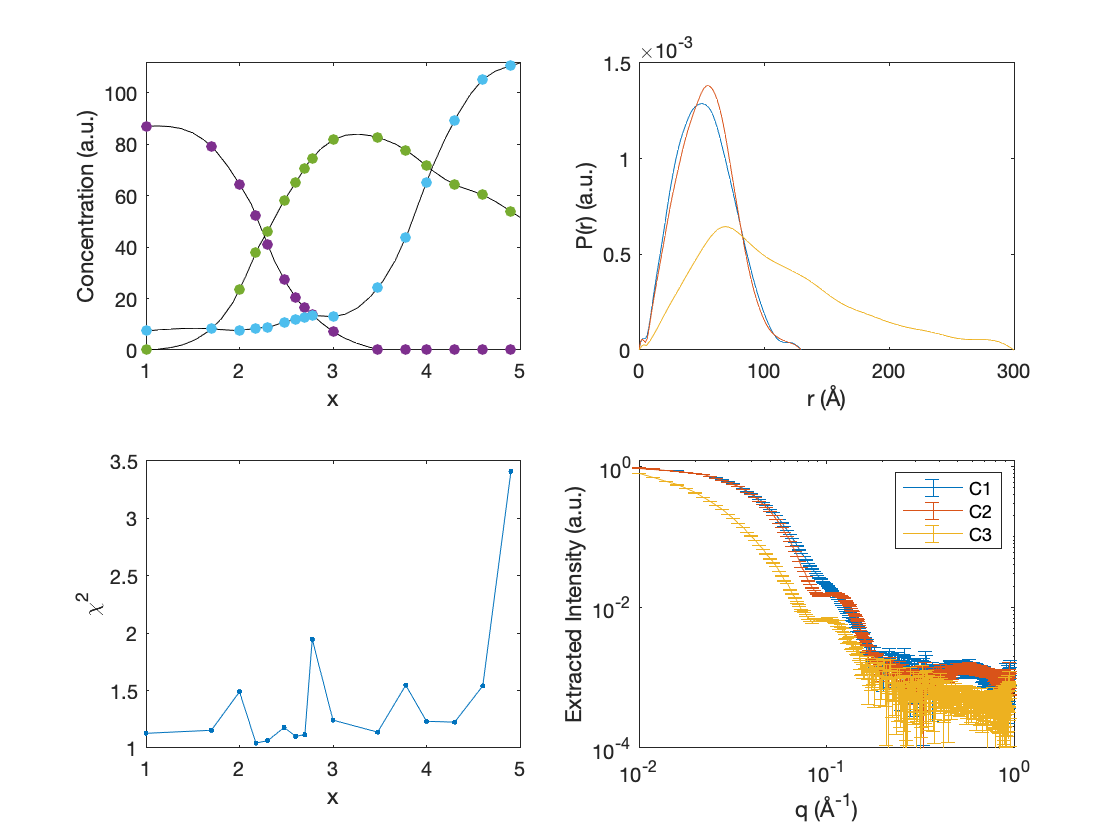

figure(1);clf;
subplot(2,2,1);
plot(x1,c1,'k-',x2,c2,'k-',x3,c3,'k-');hold on;
scatter(x,p1,30,'filled');hold on;scatter(x,p2,30,'filled');
scatter(x,p3,30,'filled');
xlabel('x');ylabel('Concentration (a.u.)');set(gca,'Xlim',[1,5])
subplot(2,2,3);
plot(x,mean(resid.^2,1),'.-');
xlabel('x');ylabel('\chi^2');set(gca,'Xlim',[1,5])
subplot(2,2,2);
plot(r1,pr1,r2,pr2,r3,pr3);xlabel('r (Å)');ylabel('P(r) (a.u.)');
subplot(2,2,4);
errorbar(q,I1,sigma1,'DisplayName','C1');hold on;
errorbar(q,I2,sigma2,'DisplayName','C2');
errorbar(q,I3,sigma3,'DisplayName','C3');
set(gca,'XScale','Log','Yscale','Log','Ylim',[1E-4,1.2E0]);
legend show; xlabel('q (Å^{-1})'); ylabel('Extracted Intensity (a.u.)');